% import excel file with zscore data
zscore_data = readtable('zscore_data.xlsx');
zscore_data = zscore_data(:,2:end);
% convert table values to array
zscore_array = table2array(zscore_data(:,2:end));


% plot
yvalues = zscore_data{:,1};
xvalues = zscore_data.Properties.VariableNames(2:end);
h = heatmap(xvalues,yvalues,zscore_array)

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {200×1 cell}
    ColorData: [200×8 double]

  Show all properties


grid off
N = 1000

N = 1000

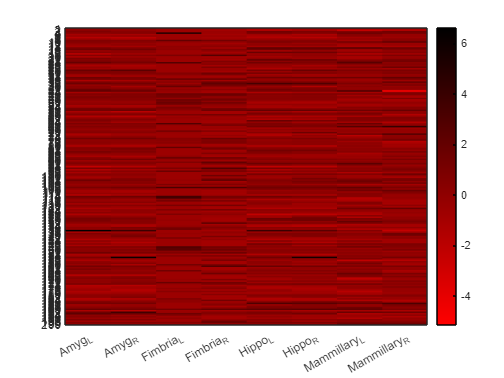

h =   HeatmapChart with properties:

        XData: {8×1 cell}
        YData: {200×1 cell}
    ColorData: [200×8 double]

  Show all properties


map = [linspace(1, 0, N)', linspace(0, 0, N)', linspace(0, 0, N)'];
%map = [1 0 0; 0 0 0; 0 0 1];
h.Colormap = map